# Построение модели цилиндра

[a b] - внутренний и внешний радиус трубки

Пока воспользуемся файлами stl, сделанными в автокаде.

## Необходимо сделать:

1) Автоматическое моделирование цилиндров в Matlab, а не перегонять STL файлы;

2) Обработать пересечения цилиндров;

3) Найти способ смыгчить вид распределения электромагнитного потенциала (он не должен быть в виде треугольника, так как это означает отсутствие производной).

# Распределение электромагнитного потенциала 1

emagmodel = createpde()
importGeometry(emagmodel,'Чертеж с дыркой 5 - 100.stl');
c = 10000;
specifyCoefficients(emagmodel,'m',0,'d',0,'c',-1,'a', 0,'f', 0);
pdegplot(emagmodel,'FaceLabels','on',  'CellLabels','on','FaceAlpha',0.5)
applyBoundaryCondition(emagmodel,'dirichlet',...
                             'Face',8,...
                             'u',c);
applyBoundaryCondition(emagmodel,'dirichlet',...
                             'Face',3:7,...
                             'u',0);
applyBoundaryCondition(emagmodel,'dirichlet',...
                             'Face',1:2,...
                             'u',0);
generateMesh(emagmodel); 
results = solvepde(emagmodel);
figure;
[cgradx,cgrady,cgradz] = evaluateCGradient(results);
pdeplot3D(emagmodel,'FlowData',[cgradx cgrady cgradz])

u = results.NodalSolution;
pdeplot3D(emagmodel,'ColorMapData', u);

[X, Y, Z] = meshgrid(0:100, 0:100, 0:100);
uintrp = interpolateSolution(results,X,Y,Z);
uintrp = reshape(uintrp,size(X));
lvls = 0:100:5000;
contourslice(X,Y,Z,uintrp,[],50,[], lvls);
colormap jet
xlabel('x')
ylabel('y')
zlabel('z')
xlim([0,100])
ylim([0,100])
zlim([0, 100])
axis equal
view(3)
colorbar

# Распределение электромагнитного потенциала 

Создание PDE модели.

emagmodel = createpde();
importGeometry(emagmodel,'Куб 50 - Три трубки параллельно.stl');
c = 10000; % значение напряжения на аноде.

Коэффициенты PDE: $m\frac{\partial^2 u}{\partial t}2+d\frac{\partial u}{\partial t}-\nabla \cdot \left(c\nabla u\right)+\textrm{au}=f$.

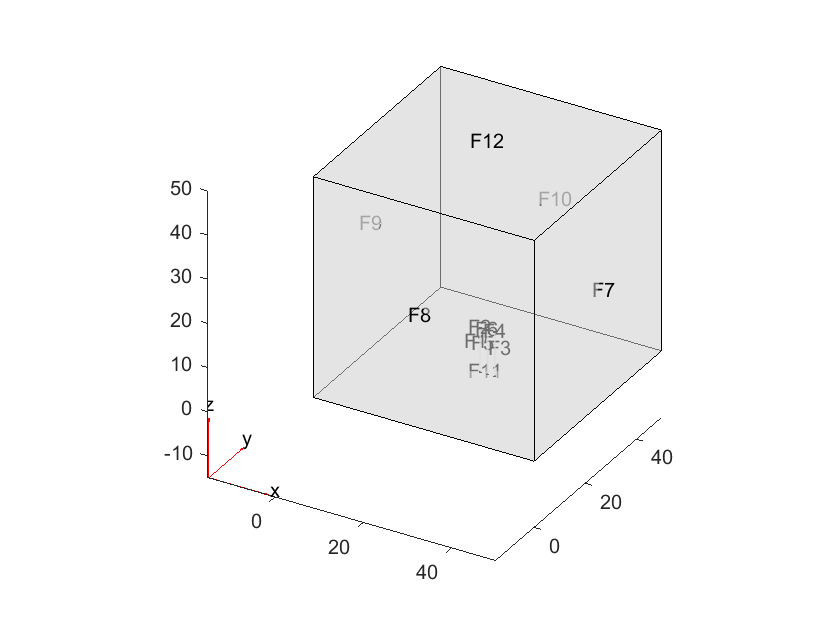

specifyCoefficients(emagmodel,'m',0,'d',0,'c',-1,'a', 0,'f', 0);
pdegplot(emagmodel,'FaceLabels','on','FaceAlpha',0.5)

Добавляем граничные условия Дирихле и Неймана.

applyBoundaryCondition(emagmodel,'dirichlet',...
                             'Face',12,...
                             'u',c);
applyBoundaryCondition(emagmodel,'neumann',...
                             'Face',8:10,...
                             'g',0);
applyBoundaryCondition(emagmodel,'dirichlet',...
                             'Face',[1:6,11],...
                             'u',0);

Создаем разбиение на симплекс-элементы и решаем PDE.

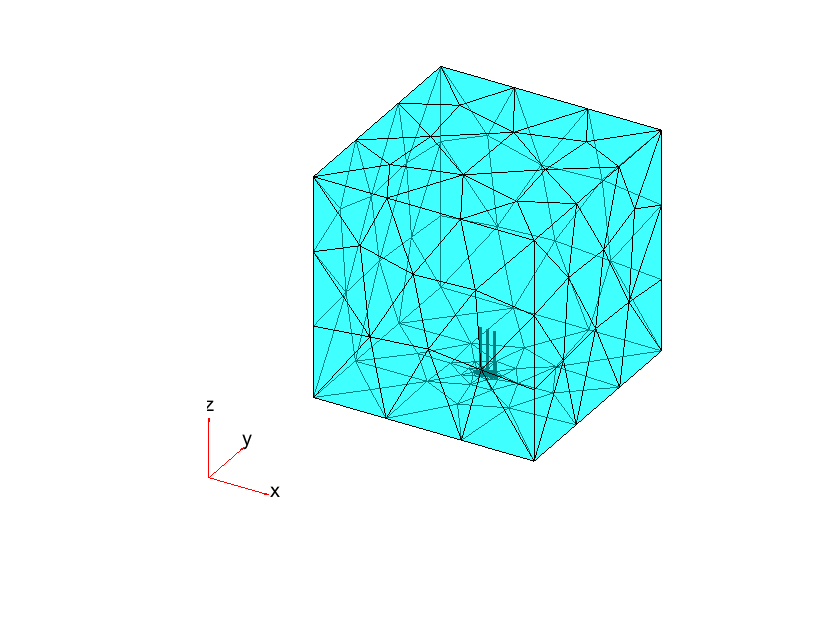

mesh = generateMesh(emagmodel, 'Hmin', 0.001, "Hmax", 15); 
pdemesh(mesh, "FaceAlpha", 0.5)

results = solvepde(emagmodel);

Построение поля изоклин

figure;
[cgradx,cgrady,cgradz] = evaluateCGradient(results);
pdeplot3D(emagmodel,'FlowData',[cgradx cgrady cgradz])

Подсчет градиента на вершинах нанотрубок

xq1 = 23;
yq1 = 25;
zq1 = 10;
[gradx1,grady1,gradz1] = evaluateGradient(results,xq1,yq1, zq1)

xq2 = 25;
yq2 = 25;
zq2 = 10;
[gradx2,grady2,gradz2] = evaluateGradient(results,xq2,yq2, zq2)

xq3 = 27;
yq3 = 25;
zq3 = 10;
[gradx3,grady3,gradz3] = evaluateGradient(results,xq3,yq3, zq3)

Интерполирование тетраедров (без интерполяции не получится посмотреть распределение потенциала слоя, так как на данный момент он построен на тетраедрах)

[X, Y, Z] = meshgrid(0:0.8:50, 0:0.8:50, 0:0.8:50);
uintrp = interpolateSolution(results,X,Y,Z);
uintrp = reshape(uintrp,size(X));
uintrp(23,25,10)
uintrp(25,25,10)
uintrp(27,25,10)

Построение цветовой карты центрального слоя

lvls = 20:80:10000;
contourslice(X,Y,Z,uintrp,[],25,[], lvls);
colormap jet
xlabel('x, нм')
ylabel('y, нм')
zlabel('z, нм')
axis equal
colorbar